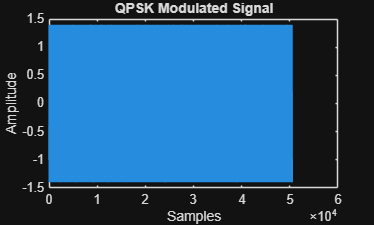

clc;
clear;
close all;

% Parameters
N = 1000;          % Number of bits
fc = 10;           % Carrier frequency
fs = 100;          % Sampling frequency
t = 0:1/fs:1;

% Generate random binary data
data = randi([0 1],1,N);

% Serial to Parallel
data_reshaped = reshape(data,2,[]);

I = data_reshaped(1,:);
Q = data_reshaped(2,:);

% Map bits (0 -> -1, 1 -> +1)
I = 2*I - 1;
Q = 2*Q - 1;

% Carrier signals
carrier_cos = cos(2*pi*fc*t);
carrier_sin = sin(2*pi*fc*t);

% QPSK modulation
qpsk_signal = [];

for i=1:length(I)
    s = I(i)*carrier_cos + Q(i)*carrier_sin;
    qpsk_signal = [qpsk_signal s];
end

% Plot transmitted signal
figure;
plot(qpsk_signal);
title('QPSK Modulated Signal');
xlabel('Samples');
ylabel('Amplitude');


% Demodulation
rx_I = [];
rx_Q = [];

for i=1:length(I)
    segment = qpsk_signal((i-1)*length(t)+1:i*length(t));

    I_demod = segment .* carrier_cos;
    Q_demod = segment .* carrier_sin;

    rx_I = [rx_I sum(I_demod)];
    rx_Q = [rx_Q sum(Q_demod)];
end

% Decision device
rx_I = rx_I > 0;
rx_Q = rx_Q > 0;

% Parallel to serial
received_data = reshape([rx_I; rx_Q],1,[]);

% BER calculation
BER = sum(data ~= received_data)/N;

disp(['Bit Error Rate: ', num2str(BER)]);

Bit Error Rate: 0
